# Rozwiązywanie równań różniczkowych

Tomasz Kowalski 313565

clc
clear
close all
e = exp(1);

_______________________________

#### Prezentacja metody Runge-Kutta.

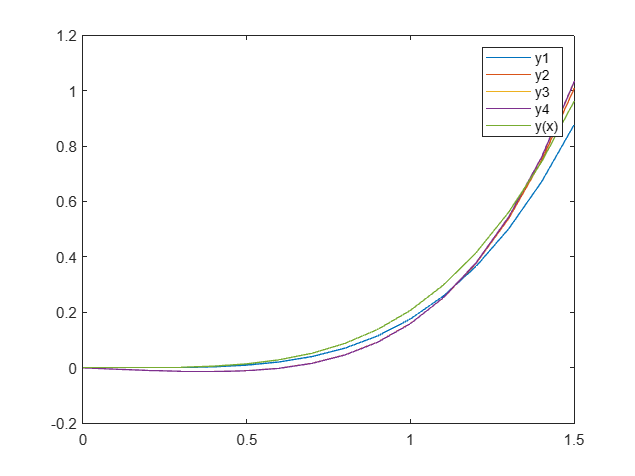

x0 = 0; 
y0 = 0;
xn = 1.5;
h = 0.1;

fun = @(x,y) x^3 - y;

yodx = @(x) x^3 - 3*x^2 + 6*x - 6 + 6*e^(-x);

x = x0:h:xn;
y1 = RKP(x0,y0,xn,h,fun,1);
y2 = RKP(x0,y0,xn,h,fun,2);
y3 = RKP(x0,y0,xn,h,fun,3);
y4 = RKP(x0,y0,xn,h,fun,4);


plot(x, y1);
hold on;
plot(x, y2);
plot(x, y3);
plot(x, y4);
plot(x, arrayfun(yodx,x));
legend('y1', 'y2', 'y3', 'y4','y(x)');
hold off;

_______________________________________

#### Prezentacja metody Adams`a-Bashforth`a.

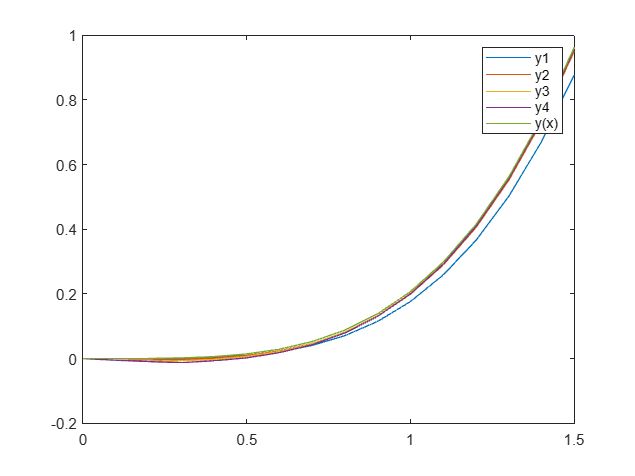

x0 = 0; 
y0 = 0;
xn = 1.5;
h = 0.1;

fun = @(x,y) x^3 - y;

yodx = @(x) x^3 - 3*x^2 + 6*x - 6 + 6*e^(-x);

x = x0:h:xn;
y1 = ABP(x0,y0,xn,h,fun,1);
y2 = ABP(x0,y0,xn,h,fun,2);
y3 = ABP(x0,y0,xn,h,fun,3);
y4 = ABP(x0,y0,xn,h,fun,4);


plot(x, y1);
hold on;
plot(x, y2);
plot(x, y3);
plot(x, y4);
plot(x, arrayfun(yodx,x));
legend('y1', 'y2', 'y3', 'y4','y(x)');
hold off;

________________________________________________

#### Prezentacja metody Runge-Kutta dla układu równań.

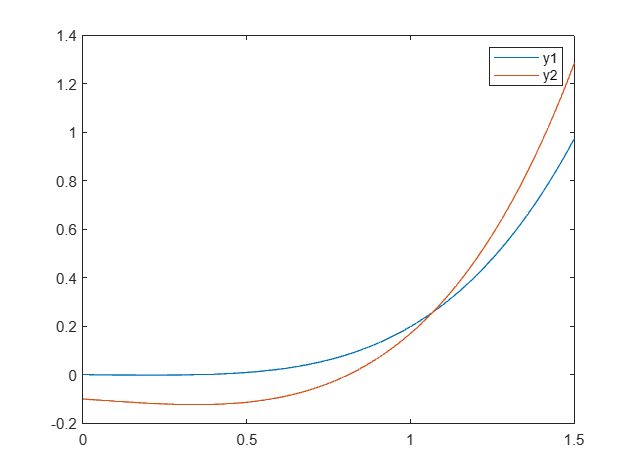

x0 = 0; 
y01 = 0;
y02 = -0.1;
xn = 1.5;
h = 0.02;
eps = 10^(-2);
r = 4;

fun1 = @(x,y) x^3 - y;
fun2 = @(x,y) x^2 + y;

yodx1 = @(x) x^3 - 3*x^2 + 6*x - 6 + 6*e^(-x);
yodx2 = @(x) -x^2 - 2*x - 2 + 19*e^(-x)/10;

x = x0:h:xn;

[xi,y1,y2] = RKU( x0, y01, y02, xn, h, fun1, fun2, r, eps);
plot(x, y1);
hold on;
plot(x, y2);
legend('y1', 'y2');
hold off;

xi

xi =     1.0600    1.0800


________________________________________________________

#### Prezentacja metody Adams`a-Bashforth`a dla układu równań.

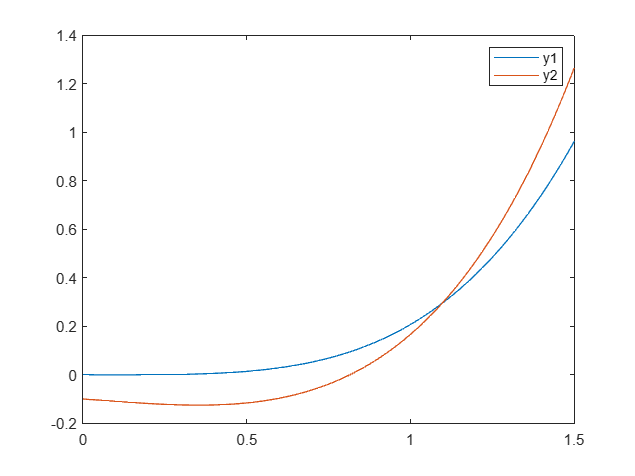

x0 = 0; 
y01 = 0;
y02 = -0.1;
xn = 1.5;
h = 0.02;
eps = 10^(-2);
r = 4;

fun1 = @(x,y) x^3 - y;
fun2 = @(x,y) x^2 + y;

yodx1 = @(x) x^3 - 3*x^2 + 6*x - 6 + 6*e^(-x);
yodx2 = @(x) -x^2 - 2*x - 2 + 19*e^(x)/10;

x = x0:h:xn;

[xi,y1,y2] = ABU( x0, y01, y02, xn, h, fun1, fun2, r, eps);
plot(x, y1);
hold on;
plot(x, y2);
legend('y1', 'y2');
hold off;

xi

xi =     1.0800    1.1000


________________________________________

#### Badanie wpływu h na metodę Runge-Kutta.

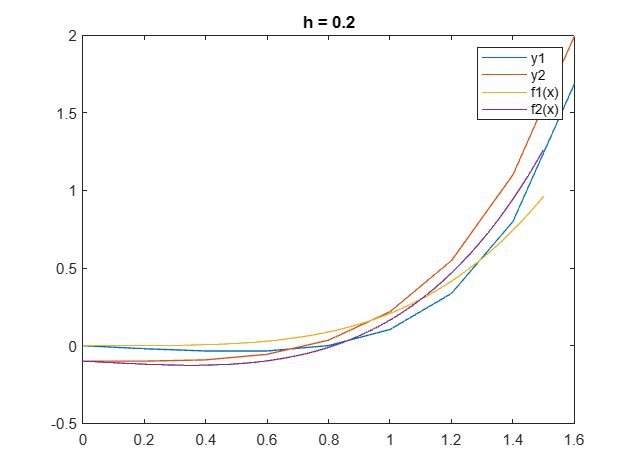

x0 = 0; 
y0 = 0;
y1 = -0.1;
xn = 1.5;
h = [0.2, 0.1, 0.05, 0.02, 0.01];
r = 4; % RZĄD METODY

fun1 = @(x,y) x^3 - y;
fun2 = @(x,y) x^2 + y;

yodx1 = @(x) x^3 - 3*x^2 + 6*x - 6 + 6*e^(-x);
yodx2 = @(x) -x^2 - 2*x - 2 + 19*e^(x)/10;

y11=RKP( x0, y0, xn, h(1), fun1, r);
y21=RKP( x0, y1, xn, h(1), fun2, r);
y12=RKP( x0, y0, xn, h(2), fun1, r);
y22=RKP( x0, y1, xn, h(2), fun2, r);
y13=RKP( x0, y0, xn, h(3), fun1, r);
y23=RKP( x0, y1, xn, h(3), fun2, r);
y14=RKP( x0, y0, xn, h(4), fun1, r);
y24=RKP( x0, y1, xn, h(4), fun2, r);
y15=RKP( x0, y0, xn, h(5), fun1, r);
y25=RKP( x0, y1, xn, h(5), fun2, r);

x1 = x0:h(1):xn+h;
x2 = x0:h(2):xn;
x3 = x0:h(3):xn;
x4 = x0:h(4):xn;
x5 = x0:h(5):xn;

plot(x1, y11);
hold on
plot(x1, y21);
plot(x5, arrayfun(yodx1,x5));
plot(x5, arrayfun(yodx2,x5));
title('h = 0.2');
legend('y1', 'y2', 'f1(x)', 'f2(x)');
hold off

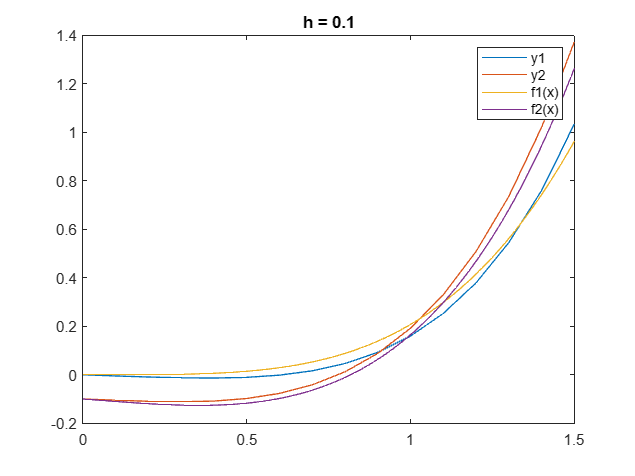

plot(x2, y12);
hold on
plot(x2, y22);
plot(x5, arrayfun(yodx1,x5));
plot(x5, arrayfun(yodx2,x5));
title('h = 0.1');
legend('y1', 'y2', 'f1(x)', 'f2(x)');
hold off

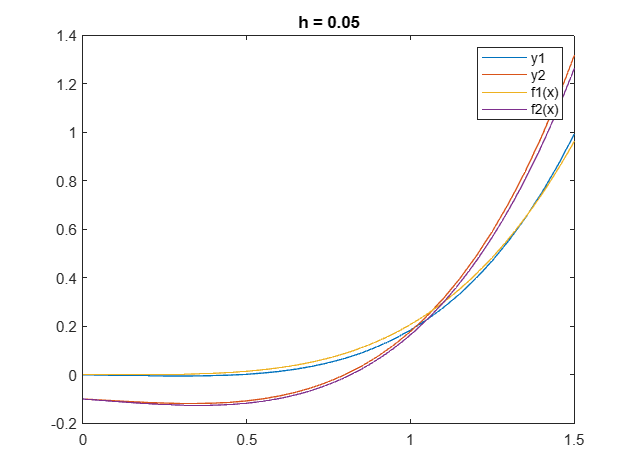

plot(x3, y13);
hold on
plot(x3, y23);
plot(x5, arrayfun(yodx1,x5));
plot(x5, arrayfun(yodx2,x5));
title('h = 0.05');
legend('y1', 'y2', 'f1(x)', 'f2(x)');
hold off

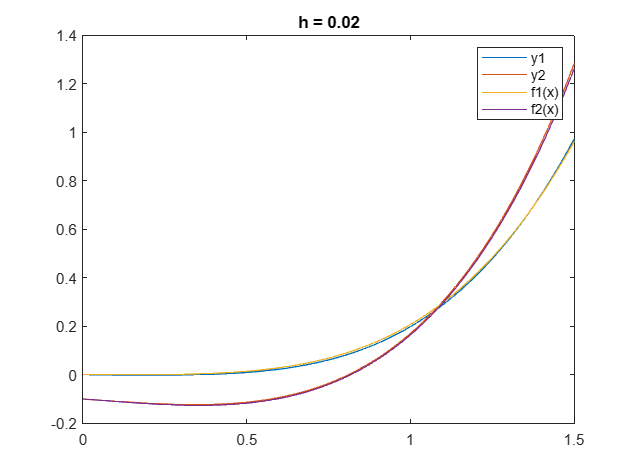

plot(x4, y14);
hold on
plot(x4, y24);
plot(x5, arrayfun(yodx1,x5));
plot(x5, arrayfun(yodx2,x5));
title('h = 0.02');
legend('y1', 'y2', 'f1(x)', 'f2(x)');
hold off

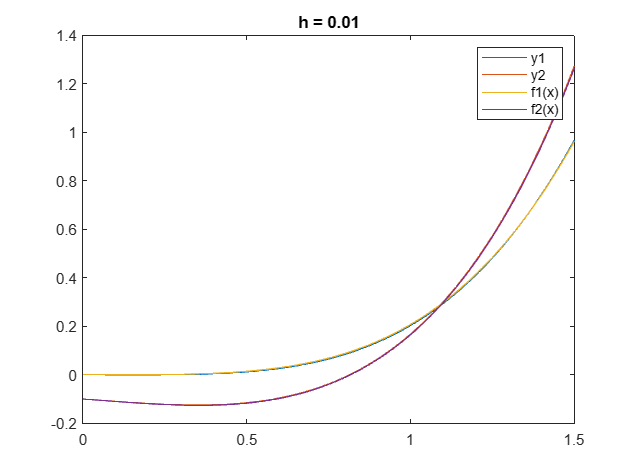


plot(x5, y15);
hold on
plot(x5, y25);
plot(x5, arrayfun(yodx1,x5));
plot(x5, arrayfun(yodx2,x5));
title('h = 0.01');
legend('y1', 'y2', 'f1(x)', 'f2(x)');
hold off

**Możemy zaobserwować że wraz ze zmiejszeniem się kroku h zwiększa się dokładność rozwiązania równania. Oczywiście wszystko zależy od rzędu w naszej metodzie. Możemy go łatwi zmienić i zobaczyć różnice jakie są między różnymi rzędami metody.**

________________________________________________

#### Badanie wpływu h na metodę Adams`a-Bashforth`a.

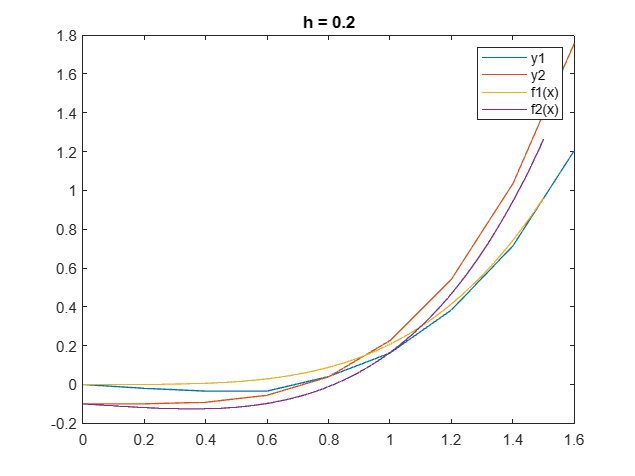

x0 = 0; 
y0 = 0;
y1 = -0.1;
xn = 1.5;
h = [0.2, 0.1, 0.05, 0.02, 0.01];
r = 4; % RZĄD METODY

fun1 = @(x,y) x^3 - y;
fun2 = @(x,y) x^2 + y;

yodx1 = @(x) x^3 - 3*x^2 + 6*x - 6 + 6*e^(-x);
yodx2 = @(x) -x^2 - 2*x - 2 + 19*e^(x)/10;


y11=ABP( x0, y0, xn, h(1), fun1, r);
y21=ABP( x0, y1, xn, h(1), fun2, r);
y12=ABP( x0, y0, xn, h(2), fun1, r);
y22=ABP( x0, y1, xn, h(2), fun2, r);
y13=ABP( x0, y0, xn, h(3), fun1, r);
y23=ABP( x0, y1, xn, h(3), fun2, r);
y14=ABP( x0, y0, xn, h(4), fun1, r);
y24=ABP( x0, y1, xn, h(4), fun2, r);
y15=ABP( x0, y0, xn, h(5), fun1, r);
y25=ABP( x0, y1, xn, h(5), fun2, r);


x1 = x0:h(1):xn+h;
x2 = x0:h(2):xn;
x3 = x0:h(3):xn;
x4 = x0:h(4):xn;
x5 = x0:h(5):xn;



plot(x1, y11);
hold on
plot(x1, y21);
plot(x5, arrayfun(yodx1,x5));
plot(x5, arrayfun(yodx2,x5));
title('h = 0.2');
legend('y1', 'y2', 'f1(x)', 'f2(x)');
hold off

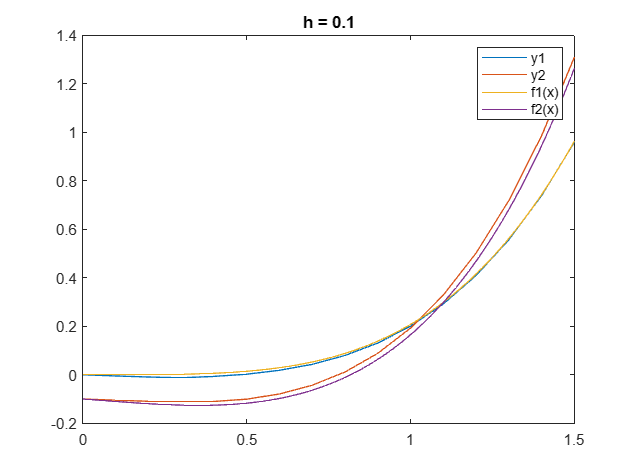

plot(x2, y12);
hold on
plot(x2, y22);
plot(x5, arrayfun(yodx1,x5));
plot(x5, arrayfun(yodx2,x5));
title('h = 0.1');
legend('y1', 'y2', 'f1(x)', 'f2(x)');
hold off

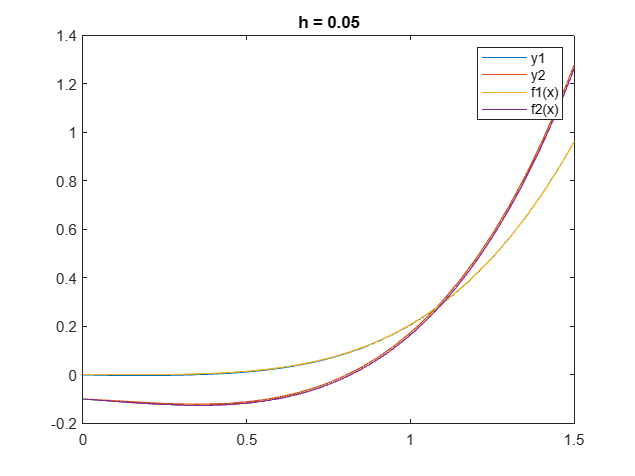

plot(x3, y13);
hold on
plot(x3, y23);
plot(x5, arrayfun(yodx1,x5));
plot(x5, arrayfun(yodx2,x5));
title('h = 0.05');
legend('y1', 'y2', 'f1(x)', 'f2(x)');
hold off

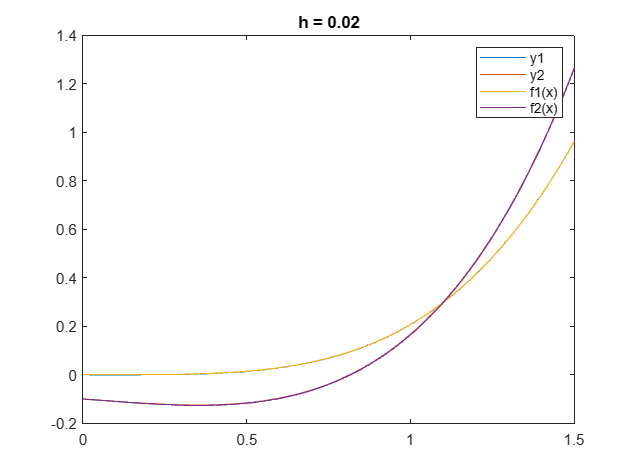

plot(x4, y14);
hold on
plot(x4, y24);
plot(x5, arrayfun(yodx1,x5));
plot(x5, arrayfun(yodx2,x5));
title('h = 0.02');
legend('y1', 'y2', 'f1(x)', 'f2(x)');
hold off

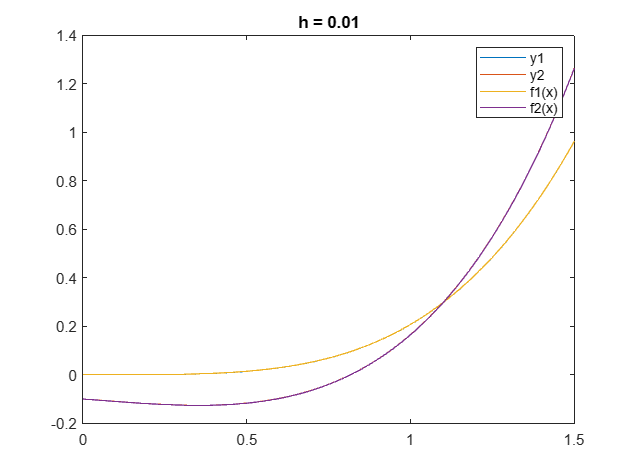


plot(x5, y15);
hold on
plot(x5, y25);
plot(x5, arrayfun(yodx1,x5));
plot(x5, arrayfun(yodx2,x5));
title('h = 0.01');
legend('y1', 'y2', 'f1(x)', 'f2(x)');
hold off

**Możemy zaobserwować że wraz ze zmiejszeniem się kroku h zwiększa się dokładność rozwiązania równania. Oczywiście wszystko zależy od rzędu w naszej metodzie. Możemy go łatwi zmienić i zobaczyć różnice jakie są między różnymi rzędami metody. Wyrażnie jednka widać że metoda Adams`a-Bashforth`a jest precyzyjniejsza niż Runge-Kutta.**

Implementacja metody Runge-Kutta

function y = RKP ( x0, y0, xn, h, fun, r)
    x = x0;
    y1 = y0;
    y2 = y0;
    y3 = y0;
    y4 = y0;

    while x(end) < xn
        k11 = h*fun(x(end),y1(end));
        k12 = h*fun(x(end),y2(end));
        k13 = h*fun(x(end),y3(end));
        k14 = h*fun(x(end),y4(end));
        k22 = h*fun(x(end) + k12, y2(end) + h);
        k23 = h*fun(x(end) + k13/2, y3(end) + h/2);
        k24 = h*fun(x(end) + k14/2, y4(end) + h/2);
        k33 = h*fun(x(end) + 2*k23 - k13, y3(end) + h);
        k34 = h*fun(x(end) + k24/2, y4(end) + h/2);
        k44 = h*fun(x(end) + k34, y4(end) + h);
    
        tmp1 = y1(end) + k11;
        tmp2 = y2(end) + (k12 + k22)/2;
        tmp3 = y3(end) + (k13 + 4*k23 + k33)/6;
        tmp4 = y4(end) + (k14 + 2*k24 + 2*k34 + k44)/6;

        y1 = [ y1, tmp1];
        y2 = [ y2, tmp2];
        y3 = [ y3, tmp3];
        y4 = [ y4, tmp4];
    
        tmp = x(end) + h;
        x = [x,tmp];
    end
    switch r
        case 1
            y = y1;
        case 2
            y = y2;
        case 3
            y = y3;
        case 4
            y = y4;
    end
end

Implementacja metody Adams'a-Bashforth'a

function y = ABP ( x0, y0, xn, h, fun, r)
    x = x0;
    switch r
        case 1
            y = y0;
            while x(end) < xn
                tmp1 = y(end) + h*fun(x(end),y(end));
                y = [y,tmp1];
                x = [x, x(end)+h];
            end

        case 2
            y = RKP (x0,y0,x+h,h,fun,r);
            x = [x, x(end)+h];
            while x(end) < xn
                tmp2 = y(end) + h*(3*fun(x(end),y(end))-fun(x(end-1),y(end-1)))/2;
                y = [y,tmp2];
                x = [x, x(end)+h];
            end

        case 3
            y = RKP (x0,y0,x+2*h,h,fun,r);
            x = [x, x(end)+h];
            x = [x, x(end)+h];
            while x(end) < xn
                tmp3 = y(end) + h*(23*fun(x(end),y(end))-16*fun(x(end-1),y(end-1))+5*fun(x(end-2),y(end-2)))/12;
                y = [y,tmp3];
                x = [x, x(end)+h];
            end

        case 4
            y = RKP (x0,y0,x+3*h,h,fun,r);
            x = [x, x(end)+h];
            x = [x, x(end)+h];
            x = [x, x(end)+h];
            while x(end) < xn
                tmp1 = y(end) + h*(55*fun(x(end),y(end))-59*fun(x(end-1),y(end-1))+37*fun(x(end-2),y(end-2))-9*fun(x(end-3),y(end-3)))/24;
                y = [y,tmp1];
                x = [x, x(end)+h];
            end
    end

end

Implementacja układu metody Runge-Kutta

function [xi,y1,y2] = RKU( x0, y01, y02, xn, h, fun1, fun2, r, eps)
    y1 = RKP(x0,y01,xn,h,fun1,r);
    y2 = RKP(x0,y02,xn,h,fun2,r);
    xi = [];
    for i = 1:length(y1)
        if abs(y1(i)-y2(i))<eps
            xi = [xi,x0+(i-1)*h];
        end
    end
end

Implementacja układu metody Adams'a-Bashforth'a


function [xi,y1,y2] = ABU( x0, y01, y02, xn, h, fun1, fun2, r, eps)
    y1 = ABP(x0,y01,xn,h,fun1,r);
    y2 = ABP(x0,y02,xn,h,fun2,r);
    xi = [];
    for i = 1:length(y1)
        if abs(y1(i)-y2(i))<eps
            xi = [xi,x0+(i-1)*h];
        end
    end
end